The following experiments are based on a matrix resulting from discretization of a partial differential equation.

maxit = 120;  rtol = 1e-8;
d = 50;
A = d^2*gallery('poisson',d);
n = size(A,1)

n =         2500


b = ones(n,1);

We compare unrestarted GMRES with three different thresholds for restarting.

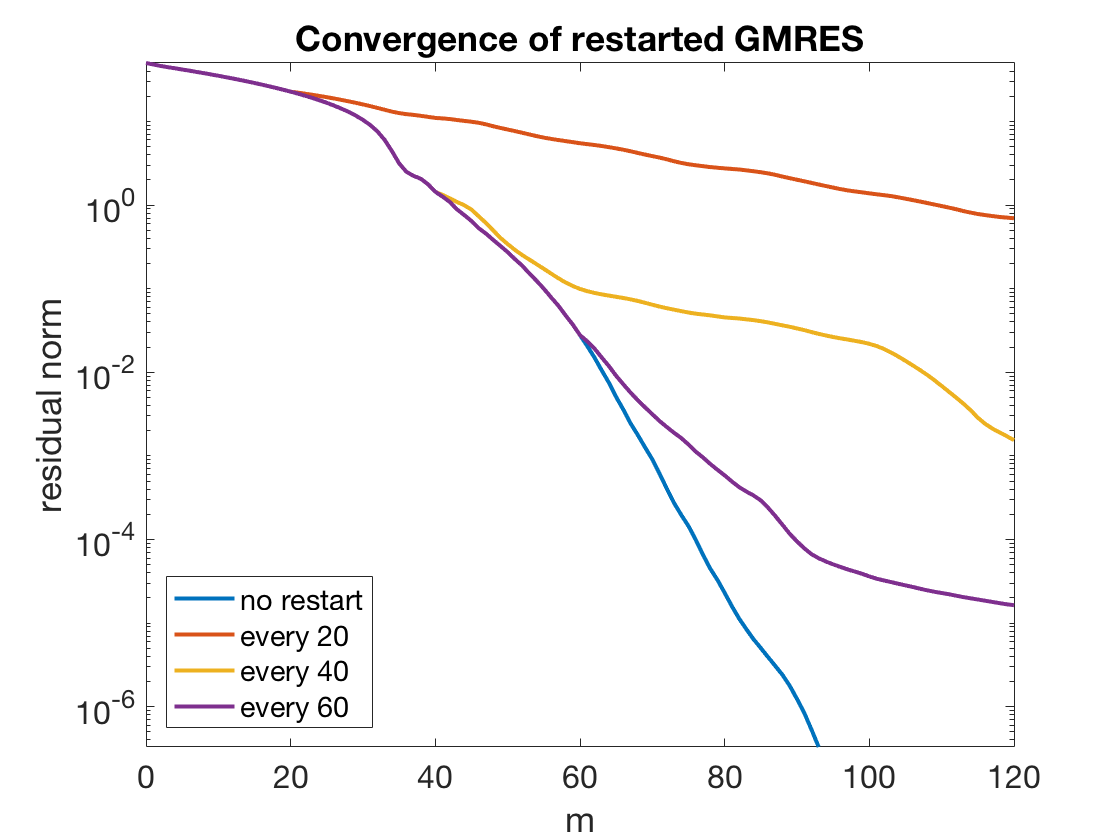

rest = [maxit 20 40 60];
for j = 1:4
    [~,~,~,~,rv] = gmres(A,b,rest(j),rtol,maxit/rest(j));
    semilogy(0:length(rv)-1,rv,'-'), hold on
end
axis tight, title('Convergence of restarted GMRES')    % ignore this line
xlabel('m'), ylabel('residual norm')   % ignore this line
legend('no restart','every 20','every 40','every 60','location','southwest')    % ignore this line

The ``pure'' curve is the lowest one. All of the other curves agree with it until they encounter their first restart. 